% Laden der Daten im Tabellenformat - In separate Datei:
% BILD | 2€ | 1€ | 0.50€ | 0.20€ | 0.10€ | 0.05€ | 0.02€ | 0.01€ || Jeweils
% mit Positionen (also lieber Dict mit Bild=>Münze?)
trainFeatures = 0;

% Plotten einiger Dateistrukturen, um sich einen Überblick über die Daten
% zu machen
% plot()

% Neurales Netzwerk erstellen
net = patternnet

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

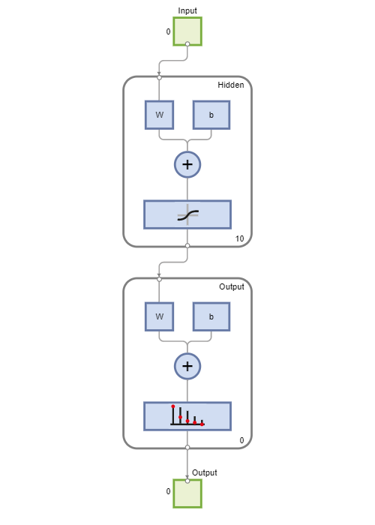

% Netz untersuchen, mit layers, weights, bias
view(net)

net.layers(1)

ans = 1×1 cell array
    {1×1 struct}


net.layers(2)

ans = 1×1 cell array
    {1×1 struct}


lweights = net.LW

lweights = 2×2 cell array
    {0×0  double}    {0×0 double}
    {0×10 double}    {0×0 double}


biases = net.b

biases = 2×1 cell array
    {10×1 double}
    { 0×1 double}


% Unterteilung der Datennutzung fürs Trainieren, Validieren und Testen.
net.divideParam.trainRatio = 0.7;
net.divideParam.valRation = 0.15;

net.divideParam.testRatio = 0.15;

% Daten vorbereiten
xTrain = trainFeatures(:, vartype("numeric"))';

Unable to use a value of type vartype as an index.

xTest = testFeatures(:, vartype("numeric"))';

yTrain = dummyvar(trainFeatures.activity)'; %Anstatt activity entsprechend Münzen?
yTest = dummyvar(testFeatures.activity)';
labels = categories(trainFeatures.activity);

% Netzwerk trainieren
net = train(net, xTrain, yTrain);

% Neue Netzwerkparameter einsehen
view(net)
net.layers(1)
net.layers(2)

% Netzwerk evaluieren
scores = net(xTest);

% Konvertieren der Evaluation für den einfacheren Vergleich
[~, yNum] = max(scores);
yPred = categorical(yNum, 1:5, labels)';

% Klassifikation für die Evaluation
yActual = testFeatures.activity;
accuracy = 100*nnz(yActial == yPred)/length(yActual)
c = confusionchart(yActual, yPred, "RowSummary", "Normalization", "row-normalized")

% Um Genauigkeit zu erhöhen
% Netzwerkparameter abändern
net.trainParam.epochs = 2000;
net.performParam.regularization = 0.05;

% Neutrainieren
net = train(net, xTrain, yTrain);